# NB-IoT sim script

## nbiot parameters

clear
numSC=12;%number subcarriers, nbiot=12
numSym=1;%number ofdm symbols, nbiot=grouped 7 per frame but more for this sim
SCS=15e3;%subcarrier spacing, nbiot=15kHz
cpLen=4;
L = 1;  % Upsampling factor



## sim parameters

%data
%numSym=round(10000/(numSC*2);
numSym=2;

randomData=false;
%channel
perfectChannel=true;%no  awgn
maxDopplerShift=1e3;
flatDoppler=true;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=10; %signal to noise ratio in dB
%loops
nLoops=1;
loopSNR=false;
SNRstepsize=2;
loopDoppler=false;
dopplerStepsize=0.1e3;

plotScatterPlot=true

plotScatterPlot = logical
   1


## tx

%generate data
dataLength=numSym*numSC*2;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    symbol=3;%generate symbols with certain value {0-3}
    messageBits=transpose(repmat(dec2bin(symbol,2)-'0',1,numSym*numSC));% -'0' to convert binary string to vector
end
%turn binary vector into vector of qpsk symbols
qpskSymbols=generateQpskSymbols(messageBits);

messageInts =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


qpskSymbols =   -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i


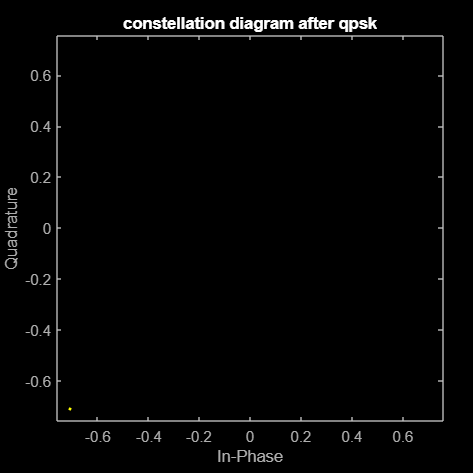


if plotScatterPlot
    %plot scatterplot
    figure;
    scatterplot(qpskSymbols);
    title('constellation diagram after qpsk');
end

ofdTimeSignal=generateOfdmSignal(qpskSymbols,numSC,SCS,cpLen)

cp =      0     0
     0     0
     0     0
     0     0


timeDomainSymbolMatrix =    0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.7071 - 0.7071i  -0.7071 - 0.7071i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i


ofdTimeSignal =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.7071 - 0.7071i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i



% BW=SCS*numSC;
% samplingRate = numSC * SCS;
% symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
% SPS = round(samplingRate * symbolDuration);
% % t = (0:SPS-1) / samplingRate; %time vector
% 
% ofdmSignal = zeros(1, numSym * SPS);
% %cpLen=round(SPS/4);%cyclic prefix length
% cpLen=5;
% if L==1
%     t=(symbolDuration/(SPS+cpLen):symbolDuration/(SPS+cpLen):(symbolDuration)*numSym);%time for each sample
% 
% else
%     t=(symbolDuration/(SPS+cpLen+(L-1)*(SPS+cpLen)):symbolDuration/(SPS+cpLen+(L-1)*(SPS+cpLen)):(symbolDuration)*numSym);%time for each sample
% 
% end
% 
% 
% ofdmMatrix = zeros(numSC,numSym);%12x7 in nbiot
% for symbolIdx =1:numSym
%     ofdmMatrix(:,symbolIdx)=messageSymbols((symbolIdx-1)*numSC+1:numSC*symbolIdx);
% end
% ofdmMatrix%every column represents 12 carriers for 1 ofdm symbol
% %the entire column/symbol is transmitted at once at different freq
% 
% timeDomainSymbolMatrix = ifft(ofdmMatrix, numSC);%time domain frame, 12 samples per symbol
% %every colum contains the sample of the symbol over time, the column
% %elements are transmitted one by one
% cp=timeDomainSymbolMatrix(end-(cpLen-1):end,:)
% timeDomainSymbolMatrix=[cp; timeDomainSymbolMatrix]%add cp
% 
% timeDomainSymbols=reshape (timeDomainSymbolMatrix,[],1)
